clear
sysg = tf([1],[1 1 2 23]);
sys = feedback(sysg,[1]);
pole(sys)

ans =   -3.0000 + 0.0000i
   1.0000 + 2.6458i
   1.0000 - 2.6458i


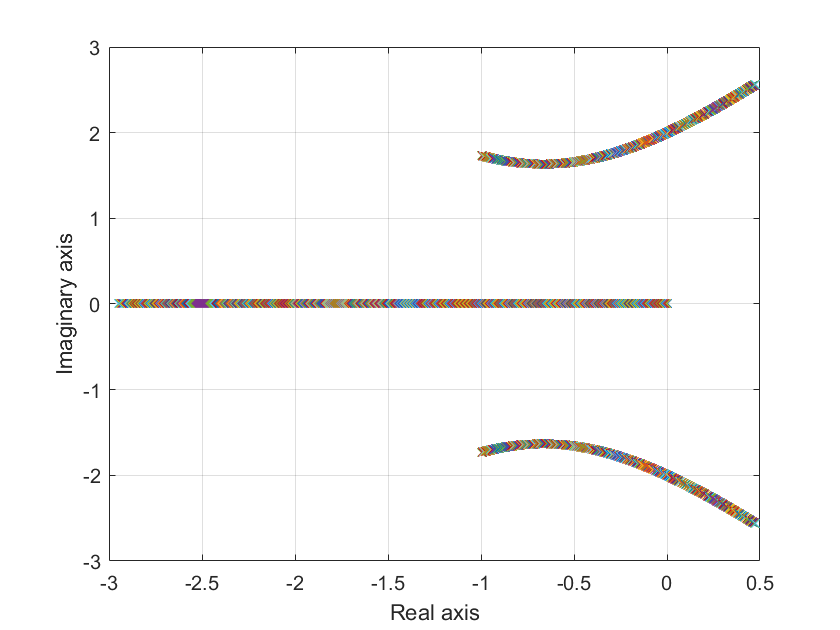

clear
K = [0:0.01:20];
for i = 1:length(K)
    q = [1 2 4 K(i)];
    p(:,i) = roots(q);
end
plot(real(p),imag(p),'x'),grid on;
xlabel('Real axis'),ylabel('Imaginary axis')

clear
a = [0.1:0.01:3.0];
K = [10:0.1:120];
x = 0*K,y = 0*K;

x =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


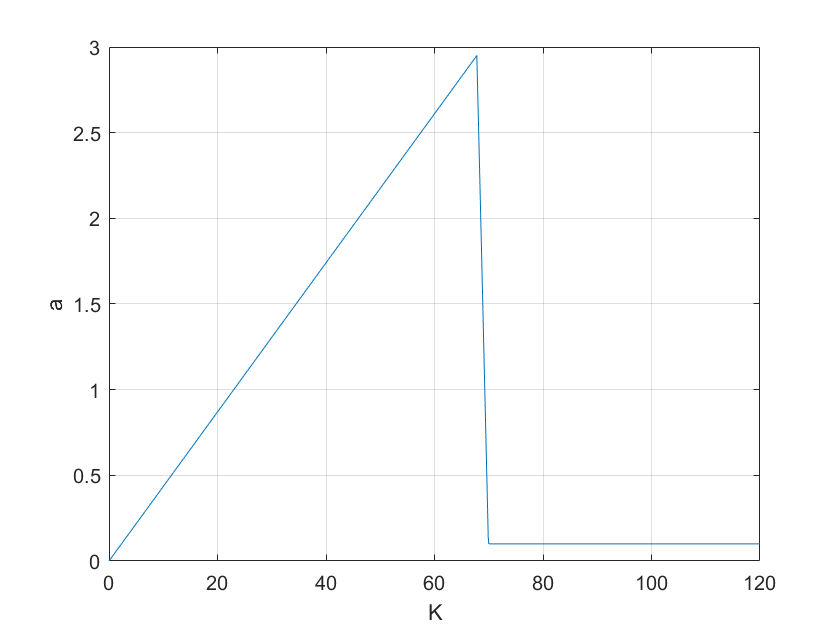

n = length(K);
m = length(a);
for i = 1:n
    for j = 1:m
        q = [1 8 17 K(i)+10 K(i)+a(j)];
        p = roots(q);
        if max(real(p)) > 0,x(i)=K(i);
            y(i) = a(j);
            break;
        end
    end
end
plot(x,y),grid on;
xlabel('K'),ylabel('a');

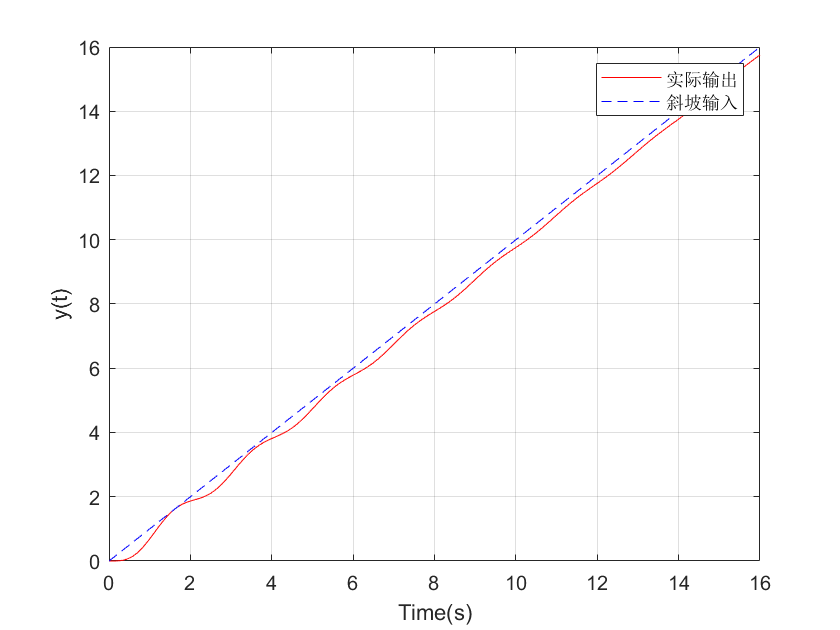

clear 
t = [0:0.01:16];
u = t;
sysgc = tf([1 0.6],[1 1]);
sysg = tf([70],[1 7 10 0]);
sysa = series(sysgc,sysg);
sys = feedback(sysa,[1]);
y = lsim(sys,u,t);
plot(t,y,'r-',t,u,'b--'),grid on;
xlabel('Time(s)'),ylabel('y(t)');
legend('实际输出','斜坡输入')

clear
A = [-8 -16 -6;1 0 0;0 1 0];
p = poly(A)

p =     1.0000    8.0000   16.0000    6.0000


roots(p)

ans =    -5.0861
   -2.4280
   -0.4859


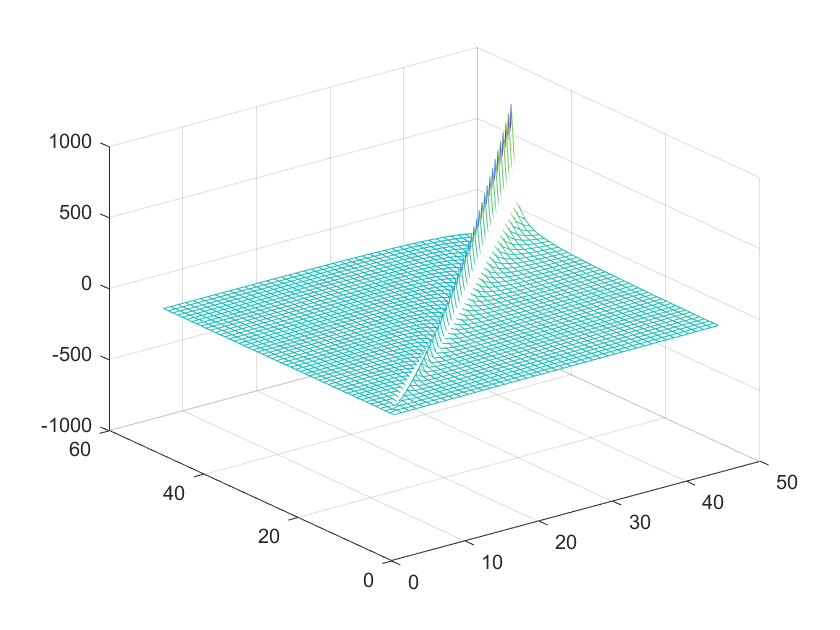

clear
[p,z] = meshgrid(1.2:0.2:10,0.1:0.2:10);
k = p.*(p-1)./(p-1-z);
mesh(k)

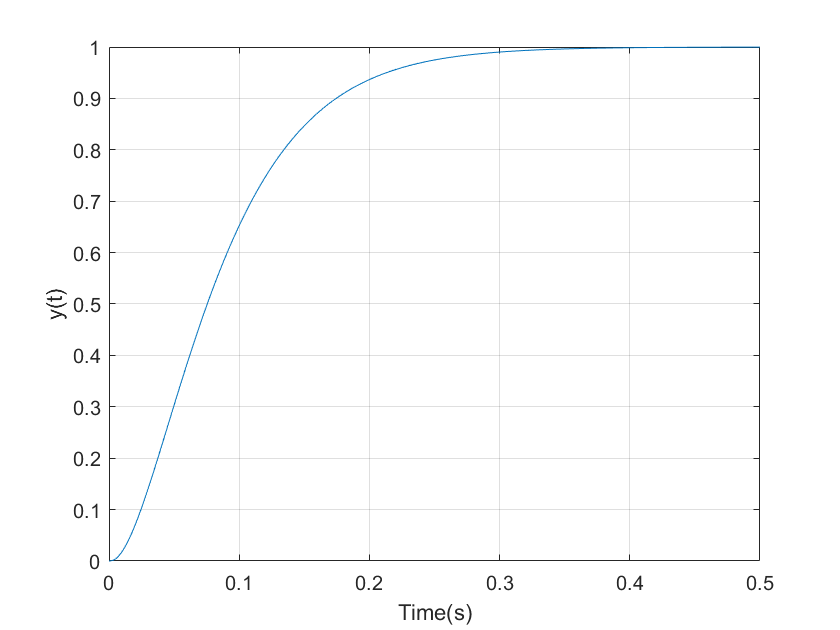

clear
Ka = 100;
K1 = 0.05;
sys1 = tf([5000],[1 1000]);
sys2 = tf([1],[1 20 0]);
sysc = tf([K1 1],[0 1]);
syso = series(Ka*sys1,sys2);
sys = feedback(syso,sysc);
sys = minreal(sys);
t = [0:0.001:0.5];
y = step(sys,t);
plot(t,y),grid on;
xlabel('Time(s)'),ylabel('y(t)');